% (exp(x+y)+3*x^2)*dx+(exp(x+y)+4*y^2)*dy=0
% y(0)=0

clear
% 1)
% y'=-(exp(x+y)+3*x^2)/(exp(x+y)+4*y^2)
syms x y(x)
eqn=diff(y(x))==-(exp(x+y)+3*x^2)/(exp(x+y)+4*y^2)

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{{\mathrm{e}}^{x+y\left(x\right)}+3\,x^{2}}{{\mathrm{e}}^{x+y\left(x\right)}+4\,{y\left(x\right)}^{2}}$$

cond=y(0)==0

$$cond = y\left(0\right)=0$$

ySol=dsolve(eqn,cond)

$$ySol = \mathrm{solve}\left({\mathrm{e}}^{x+y}+x^{3}+\frac{4\,y^{3}}{3}-1,y\right)$$

% solve(exp(x + y) + (4*y^3)/3 == 1 - x^3, y)
% exp(x + y) + (4*y^3)/3 == 1 - x^3

% 2)
syms x y dx dy C
eq1=(exp(x+y)+3*x^2)*dx+(exp(x+y)+4*y^2)*dy

$$eq1 = \mathrm{dx}\,\left({\mathrm{e}}^{x+y}+3\,x^{2}\right)+\mathrm{dy}\,\left({\mathrm{e}}^{x+y}+4\,y^{2}\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} {\mathrm{e}}^{x+y}+3\,x^{2} & {\mathrm{e}}^{x+y}+4\,y^{2} \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = {\mathrm{e}}^{x+y}+3\,x^{2}$$

$$Q = {\mathrm{e}}^{x+y}+4\,y^{2}$$

f=simplify(diff(Q,x)-diff(P,y))

$$f = 0$$

x0=0;y0=0;
U=int(P,x,x0,x)+int(subs(Q,x,x0),y,y0,y)

$$U = {\mathrm{e}}^{y}+{\mathrm{e}}^{y}\,\left({\mathrm{e}}^{x}-1\right)+x^{3}+\frac{4\,y^{3}}{3}-1$$

eq2=U==C

$$eq2 = {\mathrm{e}}^{y}+{\mathrm{e}}^{y}\,\left({\mathrm{e}}^{x}-1\right)+x^{3}+\frac{4\,y^{3}}{3}-1=C$$

C1=solve(subs(eq2,[x y],[0 0]))

$$C1 = 0$$

eq2=simplify(subs(eq2,C,C1))/3

$$eq2 = {\mathrm{e}}^{x+y}+x^{3}+\frac{4\,y^{3}}{3}=1$$

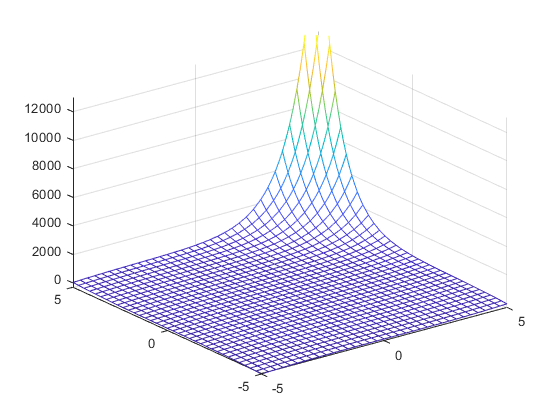

fmesh(U)